# Aproximare MCMMP

## Recensamantul SUA

Datele de mai jos au fost inregistrate de US Census intre 1900 si 2010

%CENSUS - example with census data
%          polynomial fit

%population
y = [ 75.995  91.972 105.711 123.203 131.669 150.697 ...
    179.323 203.212 226.505 249.633 281.422 308.786]';

t = (1900:10:2010)';   % census years

Dorim sa modelam datele si sa facem predictii pentru anii 1975 si 2015


x = (1890:1:2019)';    % evaluation years
w = [1975,2015];       % prediction years


Vom modela datele printr-un polinom de gradul 3


$$y=c_{1}t^3+c_{2}t^2+c_{3} t+c_{4}$$


## Fitting direct


c=polyfit(t,y,3)

c =    1.0e+04 *

  -0.000000000658612   0.000004773313407  -0.010899621048166   8.002871129543852


Echivalent

A=[t.^3,t.^2,t, ones(size(t))];
c=A\y

c =    0.000004127802258
  -0.015108763045669
  13.846233998925960
                   0


Rezultatele sunt inacceptabile din punct de vedere numeric.

Vom normaliza datele cu


$$s=\frac{t-\bar{t}}{\sigma(t)}$$


mt=mean(t); st=std(t);

s=(t-mt)/st;
xs=(x-mt)/st;


## Fitting cu date normalizate

coeficientii

cs=polyfit(s,y,3)

cs =    1.0e+02 *

  -0.003087056006188   0.118372207792208   0.765611977154729   1.664932142857143


sau echivalent

A=[s.^3,s.^2,s, ones(size(s))];
c=A\y

c =    1.0e+02 *

  -0.003087056006188
   0.118372207792208
   0.765611977154729
   1.664932142857142


predictiile:

zs=polyval(cs,xs);
est=polyval(cs,(w-mt)/st);

reprezentare grafica

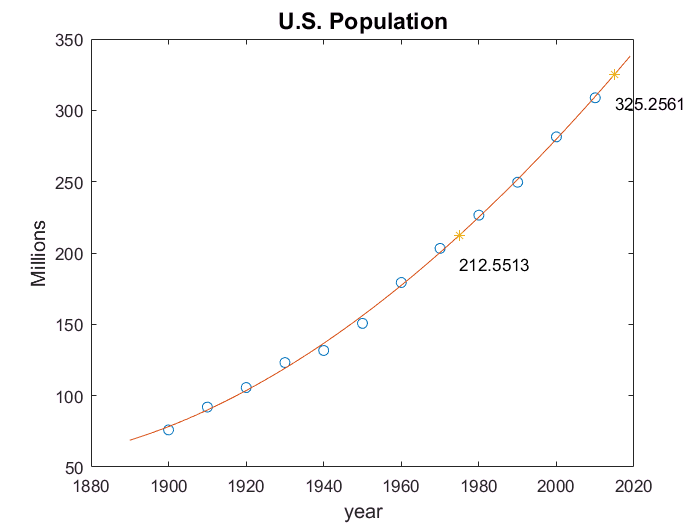

plot(t,y,'o',x,zs,'-',w,est,'*')
for i=1:length(w)
    text(w(i),est(i)-20,num2str(est(i)))
end
title('U.S. Population', 'FontSize', 14)
xlabel('year', 'FontSize', 12)
ylabel('Millions', 'FontSize', 12)